# **Diseño controlador MRAC**

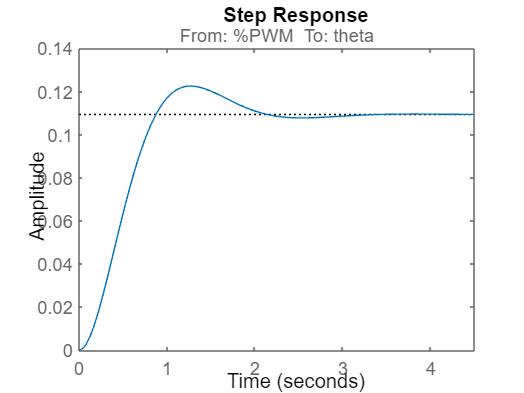

clear; clc; close all; 
addpath("../../../data/")
addpath("../../../controllers/MRAC/")
ang_Lin = 80;
[Gss] = getNewTF(ang_Lin);
step(Gss); %% Lazo abierto de planta

Definición de las prestaciones: 

- Seguimiento de Referencia Perfecto (ep = 0) 

- Accion de Control entre (0 < u < 100) [ % PWM ]

- Menor tiempo posible (Mayor ancho de banda) 

- Rechazo a perturbaciones 

Definición de señales 

- ***El controlador recibe error en radianes y lo convierte a Porcentaje de PWM % ***

## Definición Reference Model

Se define el modelo de referencia


$$\textrm{ReferenceModel}\;=\frac{a_{\textrm{ss}}^* }{s^2 +c_{\textrm{ss}}^* \cdot s+b_{\textrm{ss}}^* }=A_m \cdot x+B_m \cdot u$$


 Donde las matrices $A_m$ y $B_m$ se relacionan con la ecuación de la siguiente manera.


$$A_m =\left\lbrack \begin{array}{cc}
0 & 1\\
b_{\textrm{ss}}^*  & c_{\textrm{ss}}^* 
\end{array}\right\rbrack \;\;\;\;\;\;\;B_m =\left\lbrack \begin{array}{c}
0\\
a_{\textrm{ss}}^* 
\end{array}\right\rbrack$$


% Definición de parámetros
bss = -8.912;
css = -2*sqrt(abs(bss));%-5.5;
ass = -bss;
% Grafica de filtros 
A_RM = [0 1; bss, css];
B_RM = [0 ass]';
C_RM = [1 0;0 1];
D_RM = [0];




GRM = ss(A_RM, B_RM, C_RM, D_RM);
GRM.StateName= {'theta','omega'};
GRM.OutputName= {'theta','omega'};
GRM.InputName = {'Referencia'}

GRM =
 
  A = 
           theta   omega
   theta       0       1
   omega  -8.912  -5.971
 
  B = 
          Referencia
   theta           0
   omega       8.912
 
  C = 
          theta  omega
   theta      1      0
   omega      0      1
 
  D = 
          Referencia
   theta           0
   omega           0
 
Continuous-time state-space model.



tf(GRM)

ans =
 
  From input "Referencia" to output...
                   8.912
   theta:  ---------------------
           s^2 + 5.971 s + 8.912
 
                  8.912 s
   omega:  ---------------------
           s^2 + 5.971 s + 8.912
 
Continuous-time transfer function.




%feedback(GRM,1)


## **Comparación de Modelos**

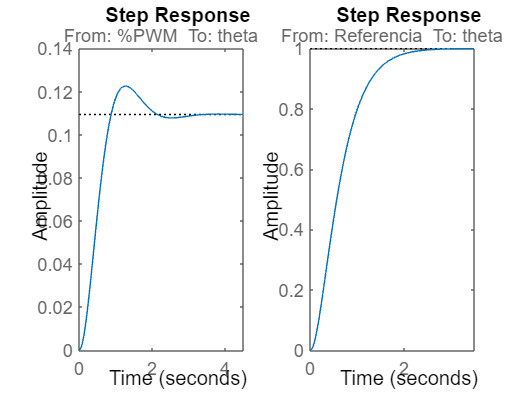

figure()
subplot(1,2,1)
step(Gss);
subplot(1,2,2)
step(GRM(1,1));


stepinfo(Gss)

ans = struct with fields:
         RiseTime: 0.589115519381643
    TransientTime: 1.960113171249475
     SettlingTime: 1.960113171249475
      SettlingMin: 0.100449015771300
      SettlingMax: 0.122540200221903
        Overshoot: 12.067701519481556
       Undershoot: 0
             Peak: 0.122540200221903
         PeakTime: 1.270772816769190


stepinfo(GRM(1,1))

ans = struct with fields:
         RiseTime: 1.124959125073956
    TransientTime: 1.954281658664590
     SettlingTime: 1.954281658664590
      SettlingMin: 0.901944935378265
      SettlingMax: 0.999914589576105
        Overshoot: 0
       Undershoot: 0
             Peak: 0.999914589576105
         PeakTime: 3.995377867799963


## MRAC Ideal

kri = Gss.B\GRM.B

kri =    9.144983701433521


Kxi = Gss.B\(GRM.A-Gss.A)

Kxi =    0.000398900891459  -2.705522300052155



GMRAC=ss(Gss.A+Gss.B*Kxi, Gss.B*kri, [1,0],[0]);
GMRAC.StateName= {'theta','omega'};
GMRAC.OutputName= {'theta'};
GMRAC.InputName = {'%PWM'}

GMRAC =
 
  A = 
           theta   omega
   theta       0       1
   omega  -8.912  -5.971
 
  B = 
           %PWM
   theta      0
   omega  8.912
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          %PWM
   theta     0
 
Continuous-time state-space model.



## Validación respuestas al escalón

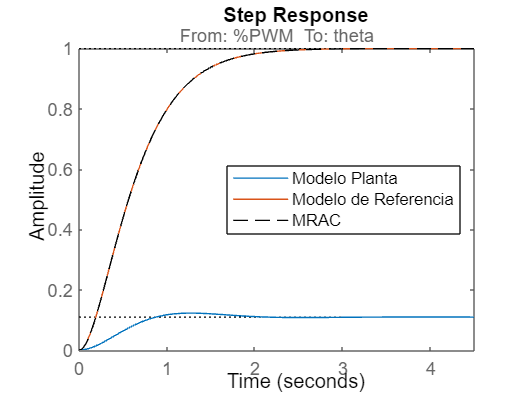

figure()
step(Gss);
hold on
step(GRM(1,1));
step(GMRAC(1,1),'k--');
hold off
legend('Modelo Planta','Modelo de Referencia','MRAC','Location','east');

## Leyes de adaptación


$${\overset{\bullet }{K_x } }^T =\Gamma_x \cdot x\cdot e^T \cdot \overset{-}{P} \cdot \textrm{sgn}\;b$$



$$\overset{\bullet }{k_r } =\gamma_r \cdot r\cdot e^T \cdot \overset{-}{P} \cdot \textrm{sgn}\;b$$


## Ley de Control


$$u\;=K_x \left(t\right)\cdot x+k_r \left(t\right)\cdot r$$


Q = eye(2);
R = 10;
[K, Pmatrix, P] = lqr(GRM,Q,R);
Pbarra = Pmatrix*[0 1]';
Gamma_x = [700 0; 0 1];%60*eye(2);
gamma_r = 30;

syms P11 P12 P21 P22
P = [P11 P12; P21 P22];
Sol = solve(GRM.A'*P+P*GRM.A+Q==0)

Sol = struct with fields:
    P11: (1739*5^(1/2)*1114^(1/2))/111400
    P12: 125/2228
    P21: 125/2228
    P22: (6195*5^(1/2)*1114^(1/2))/4963984


Sol = [Sol.P11 Sol.P12; Sol.P21 Sol.P22]

$$Sol = \left(\begin{array}{cc} \frac{1739\,\sqrt{5}\,\sqrt{1114}}{111400} & \frac{125}{2228}\\ \frac{125}{2228} & \frac{6195\,\sqrt{5}\,\sqrt{1114}}{4963984} \end{array}\right)$$

Pmatrix2 = double(Sol)

Pmatrix2 =    1.165043091026993   0.056104129263914
   0.056104129263914   0.093140493630032


Pmatrix

Pmatrix =    1.147570557698557   0.054767558539219
   0.054767558539219   0.087790417522091


## Leyes de adaptación (SISO primer orden)


$${\overset{\bullet }{k_x } }^T =\gamma_x \cdot x\cdot e\cdot \textrm{sgn}\;b$$



$$\overset{\bullet }{k_r } =\gamma_r \cdot r\cdot e\cdot \textrm{sgn}\;b$$


## Ley de Control


$$u\;=k_x \left(t\right)\cdot x+k_r \left(t\right)\cdot r$$


Q = eye(2);
R = 10;
[K, Pmatrix, P] = lqr(GRM,Q,R);
Pbarra = Pmatrix*[0 1]';
Gamma_x = 7;%0; 0 1];%60*eye(2);
gamma_r = 0.3;

## Simulación

load("data/TF.mat")
load("data/observer.mat");

results = sim("controllers\MRAC\design\MRAC_NL.slx",100)

results =   Simulink.SimulationOutput:

                    k_r: [1x1 timeseries] 
                    k_x: [1x1 timeseries] 
                    ref: [1x1 timeseries] 
                  theta: [1x1 timeseries] 
          thetaRefModel: [1x1 timeseries] 
                   tout: [262x1 double] 
               uControl: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



t = results.tout;
uControl = results.uControl.Data;
k_x = results.k_x.Data;
k_r = results.k_r.Data;
ref = results.ref.Data;
thetaRM = results.thetaRefModel.Data;
theta = results.theta.Data;

CMD = lowpass(CMD,100,1/2.5e-3)

CMD =   12.793196332215214
  28.419424199827496
  35.122924024687521
  31.029782920800507
  27.012991737706610
  29.333192410939873
  32.154983236522604
  30.437535935559385
  28.314320328473929
  29.755618998134956


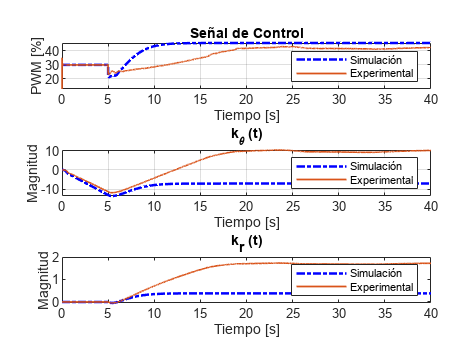


figure()
subplot(3,1,1)
plot(t,uControl,"b-.","LineWidth",1.5);
hold on
plot(timeR, CMD, 'LineWidth',1)
hold off
grid on
title('Señal de Control');
xlabel('Tiempo [s]');
ylabel('PWM [%]');
xlim([0 40])
legend('Simulación','Experimental','Location','southeast')
subplot(3,1,2)
plot(t,k_x,"b-.","LineWidth",1.5);
hold on
plot(timeR, KxR,'LineWidth',1)
hold off
grid on
title('k_\theta (t)');
xlabel('Tiempo [s]');
ylabel('Magnitud');
xlim([0 40])
legend('Simulación','Experimental','Location','east')
subplot(3,1,3)
plot(t,k_r,"b-.","LineWidth",1.5);
hold on
plot(timeR, KrR,'LineWidth',1)
hold off
title('k_r (t)');
xlabel('Tiempo [s]');
ylabel('Magnitud');
legend('Simulación','Experimental','Location','east')
xlim([0 40])

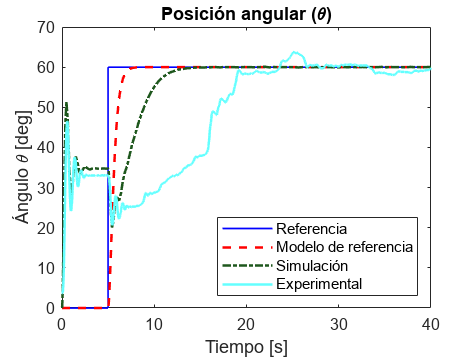


figure()
plot(t,ref,'b','LineWidth',1);
hold on
plot(t,thetaRM,'r--','LineWidth',1.5);
plot(t,theta,'Color',[30/255 87/255 29/255], 'LineStyle','-.','LineWidth',1.5);
plot(timeR,thetaR,'Color',[100/255 255/255 255/255],'LineWidth',1.5)
hold off
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [deg]');
title('Posición angular (\theta)')
legend('Referencia', 'Modelo de referencia', 'Simulación', 'Experimental','Location','southeast')
xlim([0 40])

## Implementación 1 D

Ts = 2.5e-3;
GRM = ss(A_RM, B_RM, [1 0], 0);
GRM.StateName= {'theta','omega'};
GRM.OutputName= {'theta'};
GRM.InputName = {'Referencia'};
GRM_discrete = c2d(GRM,Ts,'Tustin');
save("MRAC.mat", "Pbarra", "GRM_discrete","gamma_r","Gamma_x"); 

## Implementación 2 D

% Ts = 2.5e-3;
% GRM = ss(A_RM, B_RM, [1 0; 0 1], [0]);
% GRM.StateName= {'theta','omega'};
% GRM.OutputName= {'theta', 'omega'};
% GRM.InputName = {'Referencia'};
% GRM_discrete = c2d(GRM,Ts,'Tustin');
% save("MRAC.mat", "Pbarra", "GRM_discrete","gamma_r","Gamma_x"); 